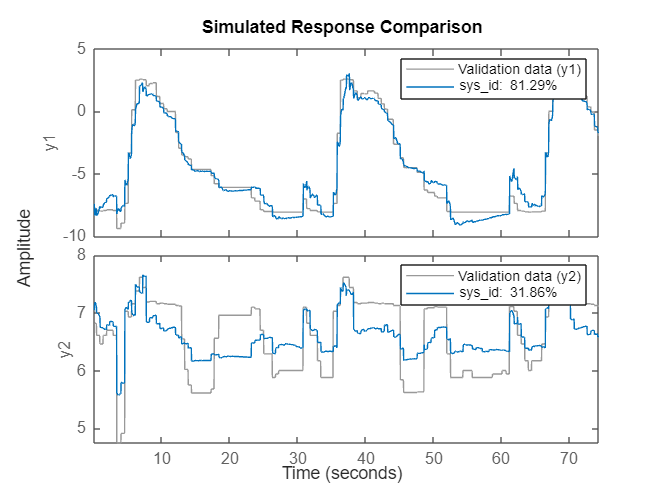

clear; clc;

% ----- 1. Data Loading -----
filepath = "C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv";
data1 = readtable(filepath); 
t = data1{1:end-1, 1};  % Time vector
Ts = t(2) - t(1);       % Sampling time

% Prepare data (normalize if needed)
x1 = data1{:, 2};
y1 = data1{:, 3};
x2 = data1{:, 4}; 
y2 = data1{:, 5};

% Normalize both x1 and y1
u = [diff(x1)/Ts, diff(y1)/Ts];  % Velocity inputs
y = [x2(1:end-1), y2(1:end-1)];  % Position outputs

% ----- 2. System Identification -----
data = iddata(y, u, Ts);
nx = 6;  % Number of states
sys_id = ssest(data, nx, 'Ts', Ts);
[A, B, C, D] = ssdata(sys_id); 

compare(sys_id, data);


% ----- 3. Optimize LQR Cost using particleswarm -----
lb = [0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01];
ub = [100, 100, 100, 100, 100, 100, 10, 10];

% Cost function handle for particleswarm
cost_fun = @(params) lqr_cost(params, A, B, C, D, y, Ts);

% Run the particle swarm optimization
[x_opt, J_opt] = particleswarm(cost_fun, 8, lb, ub);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.



% Display results
fprintf('Optimal Q: [%.2f %.2f], R: [%.2f %.2f]\n', ...
        x_opt(1), x_opt(2), x_opt(3), x_opt(4));

Optimal Q: [0.01 0.01], R: [0.01 0.01]


fprintf('Optimal Total Cost J: %.4f\n', J_opt);

Optimal Total Cost J: 0.1071



% Extract Q and R from the optimized parameters
q = nparams(1:6);   % 6 values for Q

Incorrect number or types of inputs or outputs for function nparams.

r = params(7:8);   % 2 values for R

Q = diag(q);       % 6x6
R = diag(r);       % 2x2
[K, ~, ~] = dlqr(A, B, Q, R); 

% Display the extracted LQR gain matrix K
fprintf('Extracted LQR Gain Matrix K:\n');
disp(K); 

% ----- 4. Simulation with RMSE Calculation -----
N = length(t) - 1;  % Number of time steps
x_hat = zeros(6, 1);  % 6 state estimates
u_lqg = zeros(2, N);  % 2 inputs over N timesteps
x_hist = zeros(6, N); % history of 6 state estimates
y_est = zeros(2, N);  % 2 outputs over N timesteps


% Initialize RMSE arrays
RMSE_x = zeros(1, N);
RMSE_y = zeros(1, N); 

for k = 1:N
    u_lqg(:, k) = -K * x_hat;  % LQR control law
    
    % State prediction
    x_hat = A * x_hat + B * u_lqg(:, k);
    
    % Kalman correction
    x_hat = x_hat + L * (y(k, :)' - C * x_hat); 

    Qn = eye(6) * 0.01;
    Rn = eye(2) * 0.1;
    [L, ~, ~] = dlqe(A, eye(6), C, Qn, Rn);

    
    % Store
    x_hist(:, k) = x_hat;
    y_est(:, k) = C * x_hat + D * u_lqg(:, k);
    
    % RMSE
    RMSE_x(k) = sqrt((y(k, 1) - y_est(1, k))^2);
    RMSE_y(k) = sqrt((y(k, 2) - y_est(2, k))^2);
end


% Plot RMSE Results
figure;

subplot(2,1,1);
plot(t(1:end-1), RMSE_x, 'r', 'LineWidth', 2);
title('RMSE for X Position');
xlabel('Time (s)');
ylabel('RMSE');
grid on;

subplot(2,1,2);
plot(t(1:end-1), RMSE_y, 'b', 'LineWidth', 2);
title('RMSE for Y Position');
xlabel('Time (s)');
ylabel('RMSE');
grid on;
